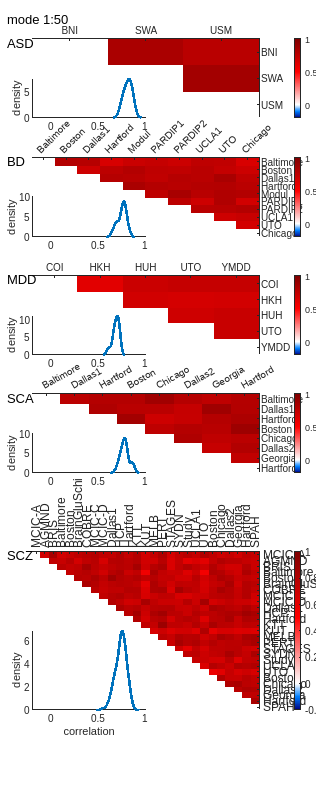

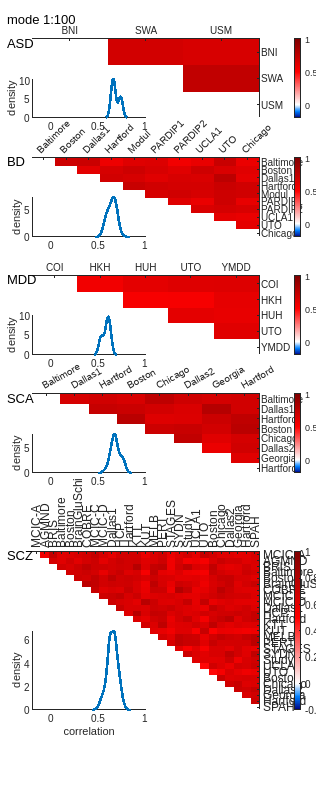

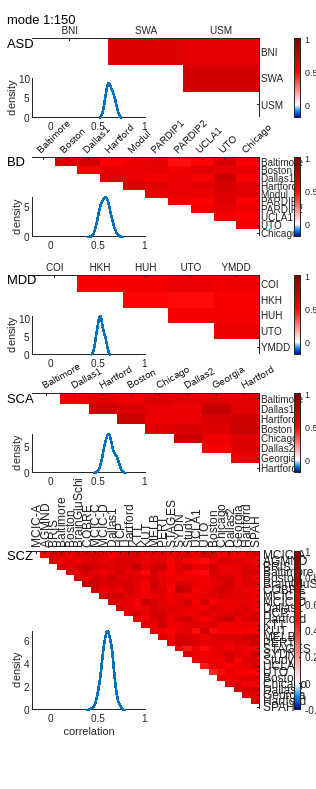

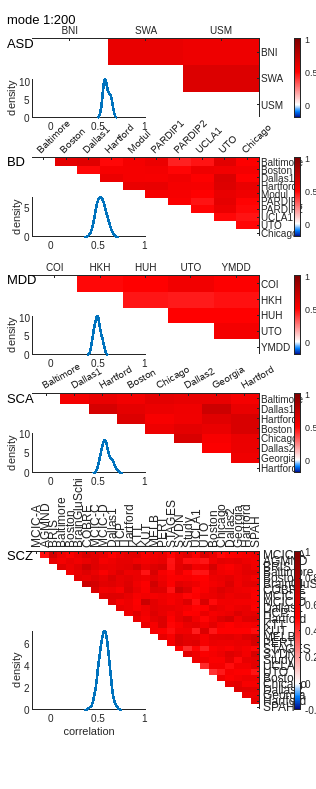

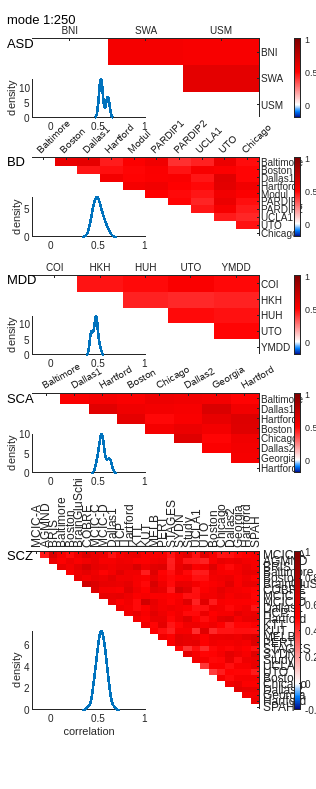

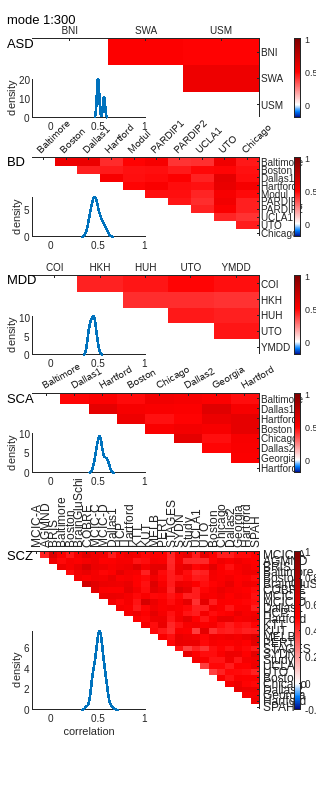

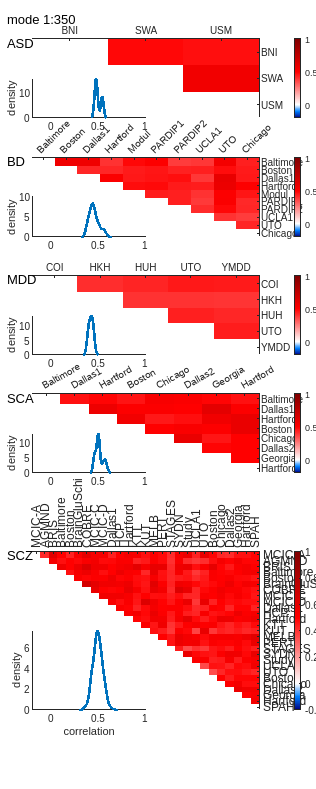

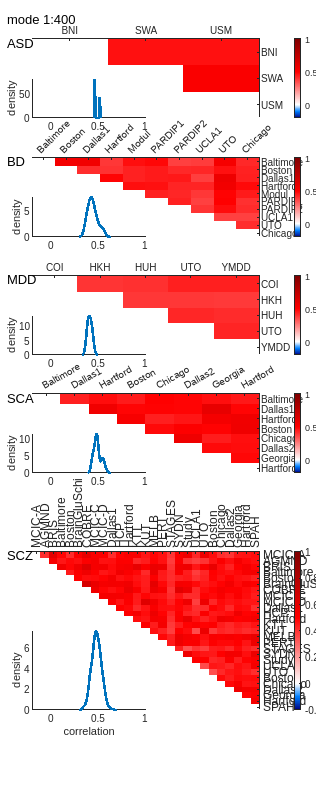

clear all
close all

diagString = {'HC', 'BD', 'SCA',...
    'SCZ', 'ASD', 'MDD' };

load('corr_MBM.mat');

nSite = length(map.numericFolders);

for nEig = 50:50:1000

    for iDiag = 2:length(diagString)

        isDiagSite = strcmp(map.diag, num2str(iDiag));
        map.corDiagRecon{iDiag} =  corr((map.beta(isDiagSite,1:nEig))');
% map.corDiagRecon{iDiag} =  corr((map.significantBeta(isDiagSite,1:nEig)* map.eig(:,1:nEig)')');

    end

    figure_corr_Recon(map, nEig)

end